Tutorial03 Assignment

2.4 Plotting Trajectories

**2.3 Wandering on a Plane - Generating Trajectories**

Now: Want to create a rand walk of 500 steps.

=> Our trajectory will be a list of 500 x values and 500 y values.

Note: It's a good practice to let MATLAB know the length of the lists, bc it saves computation time.

walklength = 500;
x = zeros(1, walklength); y = zeros(1, walklength)

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


eqn1 shows that we can consider x and y separately.

% Creating two lists of 500 random binary digits
rlistx = rand(1, walklength);
rlisty = rand(1, walklength);
stepx = (rlistx>0.5);
stepy = (rlisty>0.5);
sum(stepx);
sum(stepx);

rlistx2 = rand(1, walklength);
rlisty2 = rand(1, walklength);
stepx2 = (rlistx2>0.5);
stepy2 = (rlisty2>0.5);
sum(stepx2);
sum(stepx2);

rlistx3 = rand(1, walklength);
rlisty3 = rand(1, walklength);
stepx3 = (rlistx3>0.5);
stepy3 = (rlisty3>0.5);
sum(stepx3);
sum(stepx3);

Now, convert the lists of steps into actual successive positions of the random walker.

a)  b)

Make three random walk trajectories.

% help cumsum
stepx = cumsum(-1+2*stepx)

stepx =      1     2     1     0     1     0     1     0     1     2     3     4     3     2     3     2     3     4     5     6     5     6     5     4     3     4     3     2     1     2     3     2     3     4     3     2     1     2     1     2     3     2     1     0     1     0     1     2     3     2


stepy = cumsum(-1+2*stepy)

stepy =     -1    -2    -1    -2    -3    -4    -5    -4    -5    -4    -5    -6    -7    -8    -9    -8    -7    -8    -9    -8    -7    -8    -7    -8    -7    -8    -9   -10   -11   -12   -11   -12   -11   -10    -9   -10    -9    -8    -7    -8    -7    -6    -5    -4    -5    -6    -5    -6    -5    -6



stepx2 = cumsum(-1+2*stepx2)

stepx2 =      1     0     1     2     1     2     3     4     3     2     1     2     3     4     3     2     1     0    -1    -2    -3    -2    -3    -4    -3    -2    -1    -2    -1     0     1     0    -1    -2    -3    -2    -3    -2    -3    -2    -3    -2    -1    -2    -1     0    -1    -2    -1     0


stepy2 = cumsum(-1+2*stepy2)

stepy2 =      1     2     3     4     3     2     1     0    -1     0    -1    -2    -3    -4    -5    -4    -3    -4    -5    -6    -7    -8    -7    -6    -7    -8    -7    -8    -9   -10    -9    -8    -7    -8    -9    -8    -9   -10   -11   -12   -13   -12   -11   -12   -11   -10   -11   -10    -9   -10



stepx3 = cumsum(-1+2*stepx3)

stepx3 =      1     0     1     0    -1     0    -1     0    -1    -2    -1     0     1     2     3     2     3     2     1     2     1     0     1     2     3     4     3     4     5     6     5     4     5     4     3     4     3     2     1     0     1     2     3     2     3     4     3     4     5     4


stepy3 = cumsum(-1+2*stepy3)

stepy3 =     -1    -2    -3    -2    -3    -2    -1    -2    -3    -4    -3    -4    -3    -4    -3    -4    -3    -2    -1    -2    -1     0    -1    -2    -3    -2    -3    -2    -1     0    -1     0    -1     0     1     0     1     0    -1    -2    -3    -4    -5    -4    -3    -4    -5    -4    -3    -2


Plot 3 side by side.

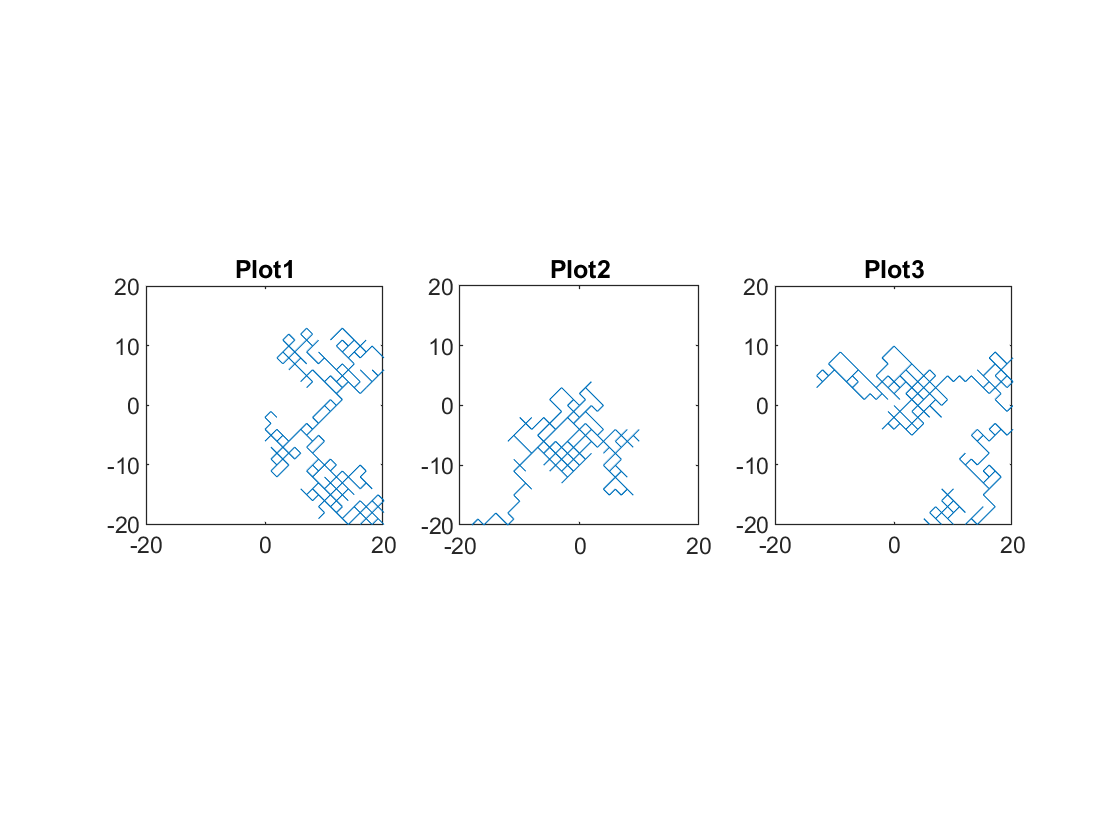

figure;
subplot(1,3,1)
plot(stepx, stepy)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot1')

subplot(1,3,2)
plot(stepx2, stepy2)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot2')

subplot(1,3,3)
plot(stepx3, stepy3)
axis equal
xlim([-20 20])
ylim([-20 20])
title('Plot3')

2.5 Plotting the 2D Random Walk Distribution

walklength = 500;

for i = 1:50
    rlistx = rand(1, walklength);
    rlisty = rand(1, walklength);
    stepx = (rlistx>0.5);
    stepy = (rlisty>0.5);
    sum(stepx), sum(stepx);
    stepx = cumsum(-1+2*stepx);
    stepy = cumsum(-1+2*stepy);
    
    xfinal(i) = stepx(500); yfinal(i) = stepy(500);
    D(i) = stepx(500)^2 + stepy(500)^2;
    
end

ans = 241

ans = 253

ans = 265

ans = 242

ans = 249

ans = 252

ans = 242

ans = 272

ans = 240

ans = 247

ans = 260

ans = 244

ans = 236

ans = 255

ans = 236

ans = 249

ans = 237

ans = 251

ans = 240

ans = 260

ans = 247

ans = 259

ans = 239

ans = 261

ans = 244

ans = 245

ans = 273

ans = 248

ans = 267

ans = 267

ans = 252

ans = 284

ans = 251

ans = 259

ans = 247

ans = 239

ans = 261

ans = 246

ans = 248

ans = 243

ans = 251

ans = 248

ans = 241

ans = 249

ans = 267

ans = 238

ans = 265

ans = 240

ans = 244

ans = 269


xfinal

xfinal =    -18     6    30   -16    -2     4   -16    44   -20    -6    20   -12   -28    10   -28    -2   -26     2   -20    20    -6    18   -22    22   -12   -10    46    -4    34    34     4    68     2    18    -6   -22    22    -8    -4   -14     2    -4   -18    -2    34   -24    30   -20   -12    38


yfinal

yfinal =     -4   -44     2     4     2    12    52    56     2   -22   -20   -44     8   -10    30     2     6     0   -10    30   -10    10   -18    22     8    34     4    -6   -56   -14   -24    14   -18     6   -36    50    22    12   -26    14    -6   -20    16    30    26     6   -28    36    12    22


D

D =          340        1972         904         272           8         160        2960        5072         404         520         800        2080         848         200        1684           8         712           4         500        1300         136         424         808         968         208        1256        2132          52        4292        1352         592        4820         328         360        1332        2984         968         208         692         392          40         416         580         904        1832         612        1684        1696         288        1928
